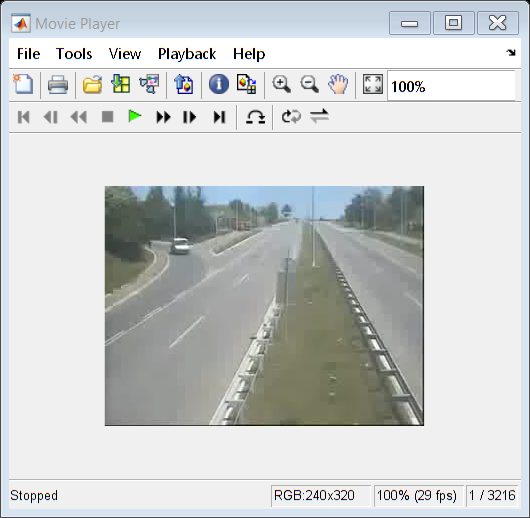

clc, clear
video = VideoReader('videoplayback.mp4');
% implay('videoplayback.mp4')xdxd

pista = read(video, 823);
pista = pista(91:240,1:150,:);

n = video.NumFrames;
k = fspecial('gaussian', 7, 3);
se = ones(11, 5);
se2 = strel('disk', 3, 0);

for i = 2:n
    
    autos = read(video, i);
    autos = autos(91:240,1:150,:);
    I2 = sum(abs(double(autos) - double(pista)), 3);
    mask1 = I2 > 125;
    
    bmf = filter2(k, mask1);
    bm2 = bmf > 0.75;
    
    dil1 = imdilate(bm2, se);
    autos1 = imclose(dil1, se2);
    
    pause(0.05)
    
    L = bwlabel(autos1); 
    
    info = regionprops(autos1, 'Centroid', 'BoundingBox', 'Eccentricity');
    
    n_blobs = max(L(:));
    
    for ind = n_blobs:-1:1 
      if info(ind).Eccentricity > 0.95
        info(ind) = []; 
      end
    end
    
    n_autos = length(info);
    subplot(1,2,1), imshow(autos);
    subplot(1,2,1),
    for ind = 1:n_autos  
      rectangle('Position', info(ind).BoundingBox,'EdgeColor','b', 'LineWidth', 1)
    end
    
end